# Line plot example

Load data file (.mat format)

load('historicalQuotes_AAPLvsIBM.mat');

Plot all AAPL and IBM closing price data

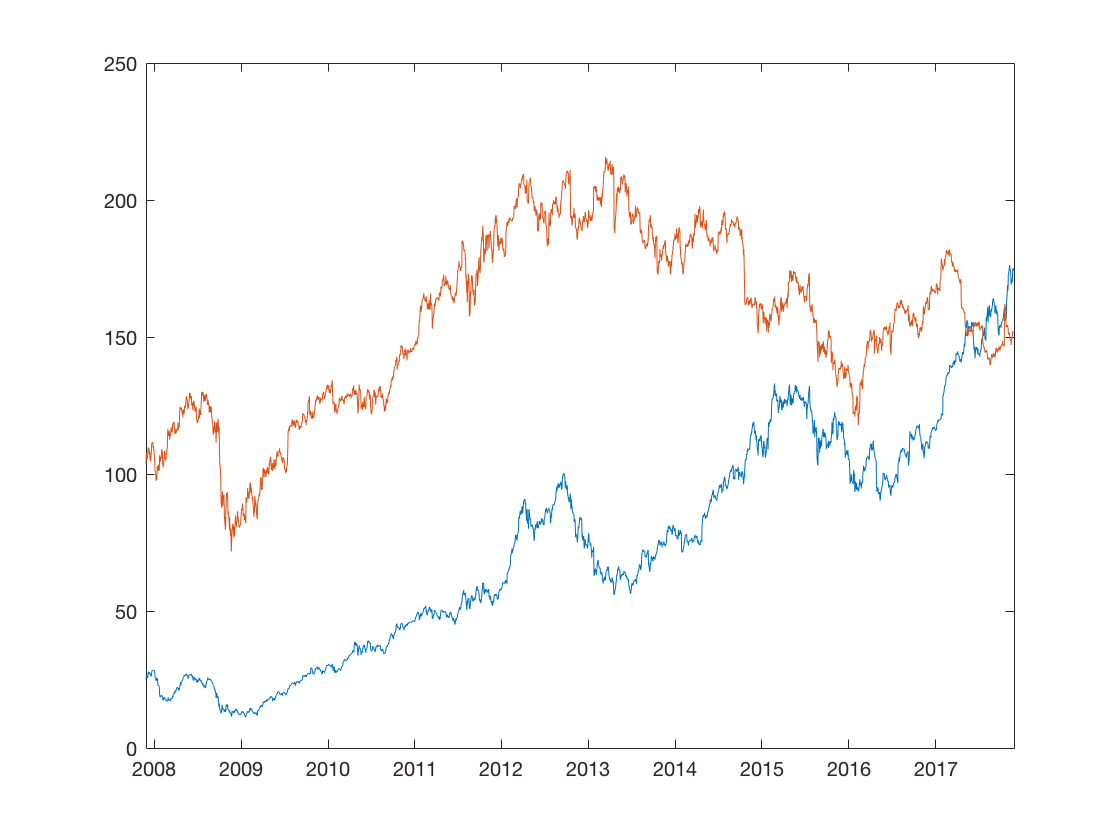

p1 = plot(AAPLt, AAPLcp);
hold on; 
p2 = plot(IBMt, IBMcp);
hold off;

ax = gca;

Add title, axis labels, and legend

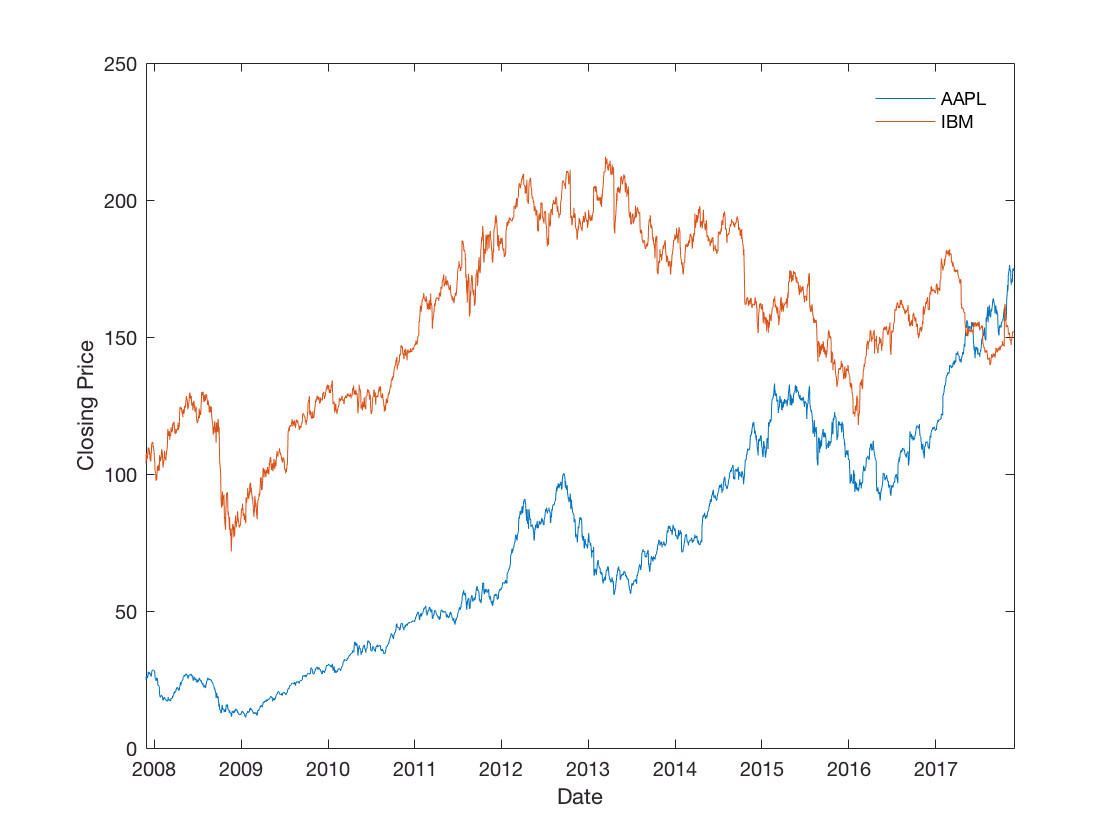

xlbl = xlabel('Date');
ylbl = ylabel('Closing Price');
legend([p1, p2], 'AAPL', 'IBM');
legend('boxoff');

Increase fontsize, linewidth

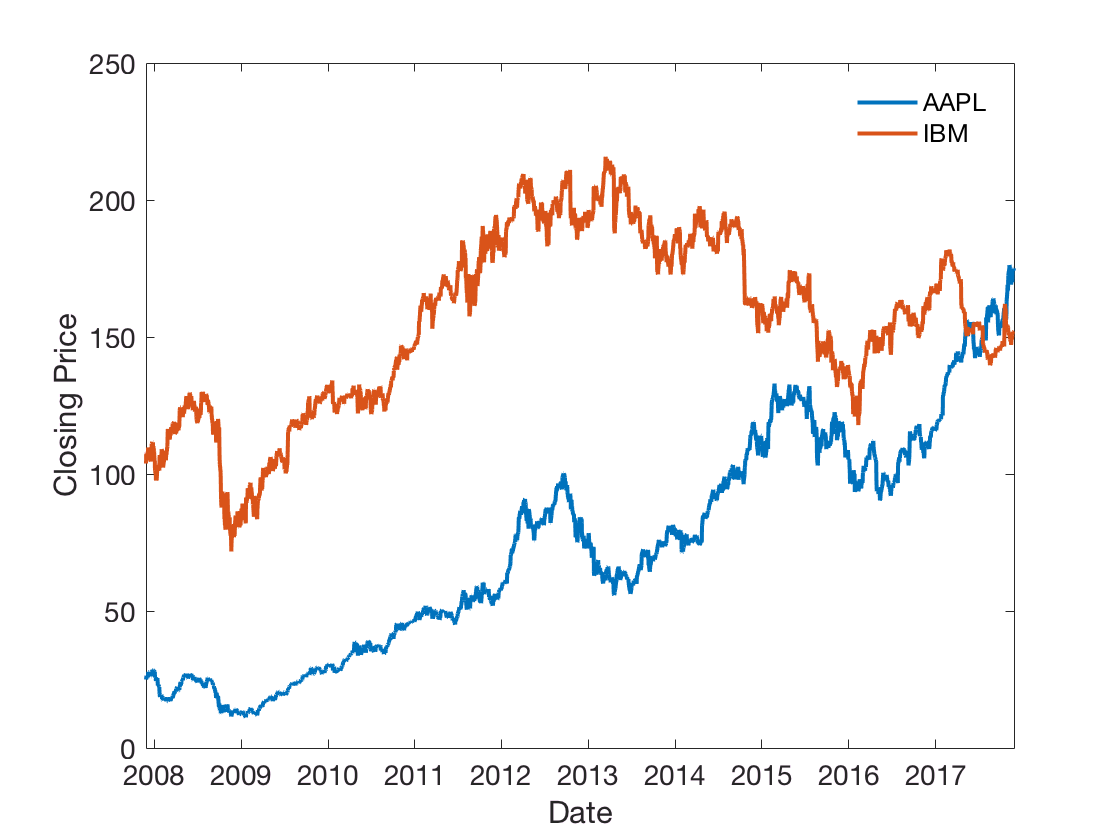

ax.FontSize = 14;
xlbl.FontSize = 16;
ylbl.FontSize = 16;
p1.LineWidth = 2;
p2.LineWidth = 2;

Zoom in on the crossing in 2017 and add high/low prices

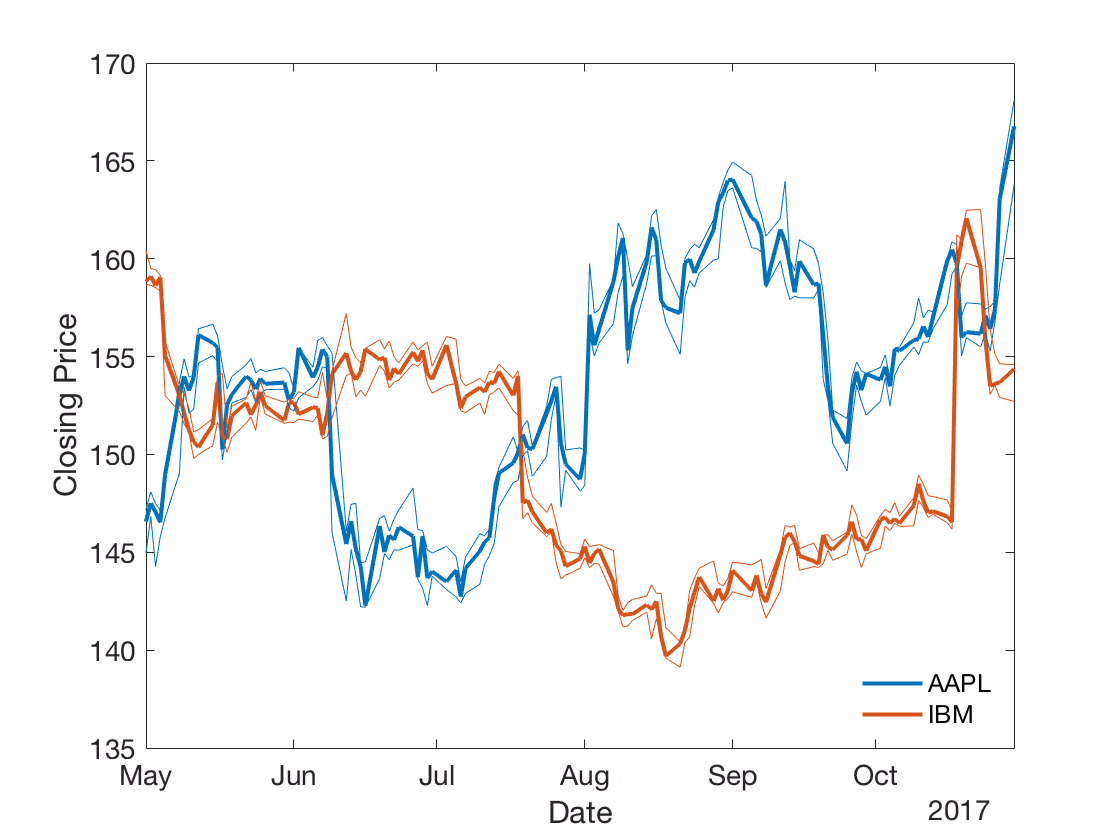

xlim(datetime(2017, [5 10], [1 30]))
xtickformat('MMM')
hold on;
p3 = plot(AAPLt, AAPLhp, AAPLt, AAPLlp);
p4 = plot(IBMt, IBMhp, IBMt, IBMlp);
hold off
p3(1).Color = [0 0.4470 0.7410];
p4(1).Color = [0.8500 0.3250 0.0980];
p3(2).Color = [0 0.4470 0.7410];
p4(2).Color = [0.8500 0.3250 0.0980];
legend([p1, p2], 'AAPL', 'IBM', 'Location', 'best');

Zoom in on July, change to dotted lines for closing price, and add markers

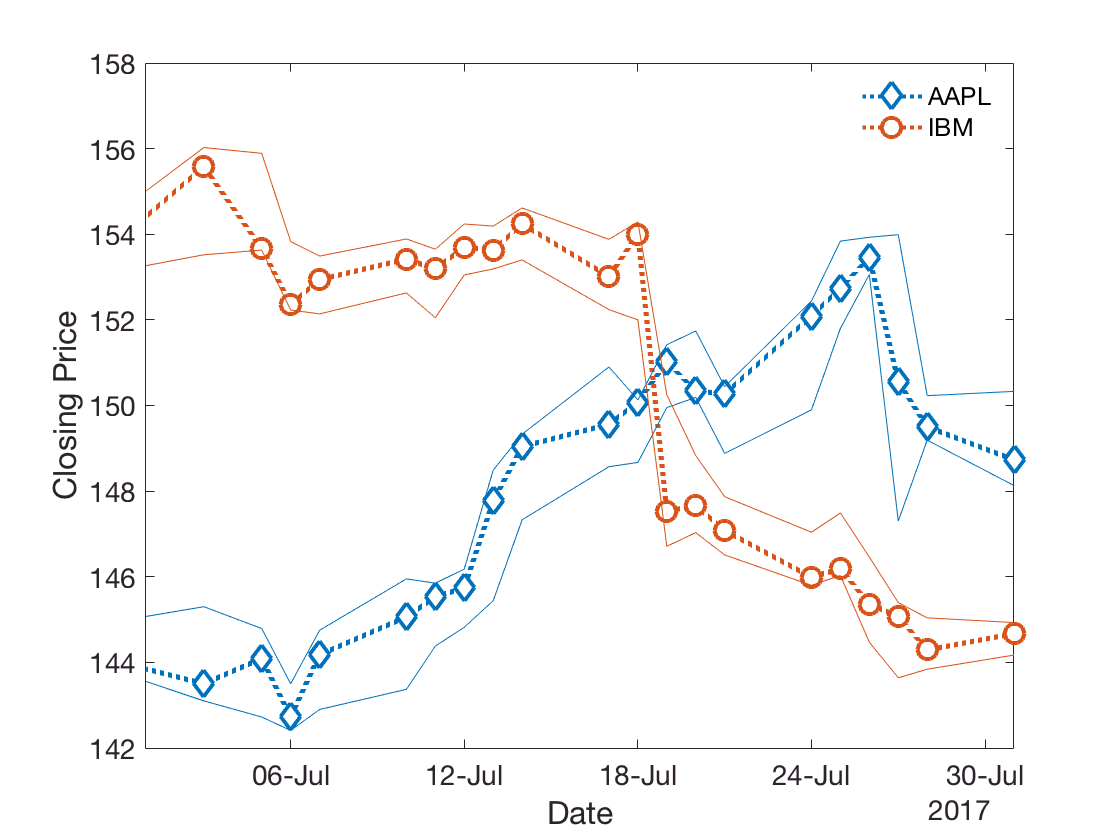

xlim(datetime(2017, 7, [1 31]))
xtickformat('dd-MMM')
legend([p1, p2], 'AAPL', 'IBM', 'Location', 'best');
p1.LineStyle = ':';
p1.Marker = 'd';
p1.MarkerSize = 10;
p1.MarkerFaceColor = 'auto';
p2.LineStyle = ':';

p2.Marker = 'o';
p2.MarkerSize = 10;
p2.MarkerFaceColor = 'auto';